# ΨΗΦΙΑΚΕΣ ΤΗΛΕΠΙΚΟΙΝΩΝΙΕΣ

## 1ο σετ Εργαστηριακών Ασκήσεων 

Λουδάρος Ιωάννης - ΑΜ 1067400

% Μεταφορά του Current Folder στον κατάλογο του αρχείου ώστε να υπάρχει
% πρόσβαση στις απαιτούμενες συναρτήσεις.

cd(fileparts(matlab.desktop.editor.getActiveFilename))

### Μέρος 1

#### LloydMax

Κατασκευάστηκε η παρακάτω συνάρτηση 

Είσοδοι:

- $x$ : Το σήμα εισόδου υπό την μορφή διανύσματος

- $N
$: Ο αριθμός των bits/sample που θα χρησιμοποιηθούν

- $max_{value$ : Η μέγιστη αποδεκτή τιμή του σήματος εισόδου

- $min_{value}$ : Η ελάχιστη αποδεκτή τιμή του σήματος εισόδου

Έξοδοι:

- $x_q$ : Το κωδικοποιημένο διάνυσμα εξόδου μετά από $K_{max}$ επαναλήψεις του αλγορίθμου

- $\text{centers}$ : Τα κέντρα των περιοχών κβάντισης μετά από $K_{max}$ επαναλήψεις του αλγορίθμου.

- $D$ : Διάνυσμα που περιέχει τις τιμές [$D_1 : D_{K_{max}}$], όπου το $D_i$ αντιστοιχεί στη μέση παραμόρφωση την i-οστή επανάληψη του αλγορίθμου

Η συνάρτηση ορίζεται στο αρχείο LloydMax.m που βρίσκεται στον ίδιο κατάλογο με το παρόν αρχείο.

**Παράδειγμα χρήσης:**

min_value = 1;
max_value = 100;
N = 4;
qlevels = linspace(min_value, max_value, 2^N+2);
qlevels = qlevels(2:end-1);
x = 120*rand(1, 100)-10

x =    99.8546   91.2609   -5.2402   69.8076   18.9287   21.2725   33.9795   17.8790   16.0366   24.1355   66.9853   92.6726   49.5518   -1.3400   38.3635   58.8611   99.5247   52.3854   58.6865   51.3281   -0.1089   11.9016   54.6854   21.5916   49.3730   51.9378    7.9144   21.4617   -8.1589   11.8943   47.6399   38.3529   69.9461   23.2033   65.3032   58.5834    2.0744   46.0411   76.1359   -5.8244   95.8481    7.2294   29.4943  104.4315   68.0691   -8.3261   38.9604  106.9811   -3.8697  103.0343






[xq, centers, D] = LloydMax(x, N, min_value, max_value)

xq = 100×4 char array
    '1111'
    '1110'
    '0000'
    '1011'
    '0010'
    '0011'
    '0101'
    '0010'
    '0010'
    '0011'
    '1010'
    '1110'
    '0111'
    '0000'
    '0110'
    '1001'
    '1111'
    '1000'
    '1001'
    '1000'
    '0000'
    '0001'
    '1000'
    '0011'
    '0111'
    '1000'
    '0001'
    '0011'
    '0000'
    '0001'
    '0111'
    '0110'
    '1011'
    '0011'
    '1010'
    '1001'
    '0000'
    '0111'
    '1100'
    '0000'
    '1111'
    '0001'
    '0100'
    '1111'
    '1010'
    '0000'
    '0110'
    '1111'
    '0000'
    '1111'
    '0011'
    '1011'
    '1001'
    '1010'
    '0000'
    '1101'
    '0111'
    '0011'
    '1111'
    '1011'
    '0000'
    '0100'
    '1101'
    '0111'
    '1011'
    '1001'
    '1001'
    '1111'
    '1000'
    '0001'
    '0011'
    '0111'
    '0000'
    '0101'
    '1001'
    '1111'
    '0000'
    '0100'
    '0000'
    '1000'
    '0011'
    '0000'
    '1111'
    '1111'
    '1110'
    '1101'
    '1011'
    '0011'
    '1111'

centers =     1.0767    8.4528   17.6148   22.4169   30.0781   34.7610   38.8485   47.9990   52.8424   58.9081   66.8411   71.2659   76.1359   83.2608   90.3591   98.9690


D =    10.2422    2.8181    2.0593    1.9195    1.8889    1.8889


#### Delta Modulation

![...]

#### Πηγές που θα χρησιμοποιηθούν

**Α. AR(1) διαδικασία**

L=10000;
x=randn(L,1);
a1=0.9;
a2=0.01;

ar1 = filter(1,[1; -a1], x);
ar2 = filter(1,[1; -a2], x);


**Β. Εικόνα**

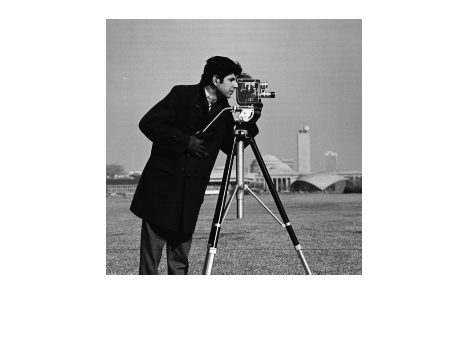

load cameraman.mat
imshow(uint8(i));

x=i(:);
x=((x-128)/128);


#### Ζητούμενο 1

![...]

#### Ζητούμενο 2

![...]

### Μέρος 2

Για το δεύτερο μέρος κατασκευάστηκαν πολλαπλές συναρτήσεις που βρίσκονται στον ίδιο κατάλογο με το παρόν αρχείο.

#### Ο Mapper

**Είσοδοι**

- bin_seq : Δυαδική ακολουθία προς μετατροπή σε σύμβολα.

- Μ : Το πλήθος των συμβόλων.

- gray : Επιλογή για το αν η ακολουθία συμβόλων θα είναι κωδικοποιημένη κατά gray (1) ή όχι (0).

**Έξοδοι**

- symbol_seq : Η ακολουθία συμβόλων που προκύπτει.

- chopped : bits της άρχικης ακολουθίας που αποκόπηκαν γιατί δεν μπορούσαν να γίνουν map.

#### Ο Demapper

**Είσοδοι**

- bin_seq : Δυαδική ακολουθία προς μετατροπή σε σύμβολα.

- Μ : Το πλήθος των συμβόλων.

- gray : Επιλογή για το αν η ακολουθία συμβόλων θα είναι κωδικοποιημένη κατά gray (1) ή όχι (0).

**Έξοδοι**

- symbols_seq : Η ακολουθία συμβόλων που προκύπτει.

- chopped : bits της άρχικης ακολουθίας που αποκόπηκαν γιατί δεν μπορούσαν να γίνουν map.

**Παράδειγμα χρήσης**

binary_seq = randsrc(100,1,[0, 1])
M=8;
gray=0;

[chopped, symbols_seq] = mapper (binary_seq, 8, 0)
binary_seq = demapper(symbols_seq, M, gray, chopped)

#### Ο Modulator

**Είσοδοι**

- symbol_seq : Τα προς μετάδοση σύμβολα.

- Μ : Το πλήθος των συμβόλων.

**Έξοδοι**

- modulated : Ο προς μετάδωση παλμός.

#### Ο Demodulator

**Είσοδοι**

- received_signal : Το σήμα που παραλάβαμε από το κανάλι.

**Έξοδοι**

- demodulated : Το demodulated σήμα.

**Παράδειγμα χρήσης**

![...]

binary_seq =      0
     0
     1
     1
     0
     1
     0
     0
     0
     0


#### O Detector

#### Ζητούμενο 1

#### Ζητούμενο 2

#### Ζητούμενο 3

#### Ζητούμενο 4

chopped = 0

symbols_seq =      1     5     0     3     4     5     1     7     4     6     5     7     7     3     3     0     2     5     1     3     4     3     2     3     2     1     3     2     1     3     2     4     7


#### Ζητούμενο 5

binary_seq = "0011010000111001010011111001101011111110110110000101010010111000110100110100010110100010110101001110"

zsh:1: no matches found: [...]
